A = [1 0.5; 0 1];
B = [0; 1];
C = [0 1];
G = ss(A, B, C, 0);
[C_i,info] = pidtune(sys,'I');
G_i = C_i*sys

G_i =
 
  A = 
        x1   x2
   x1    0    1
   x2    0  1.5
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
          x1     x2
   y1  8.185      0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



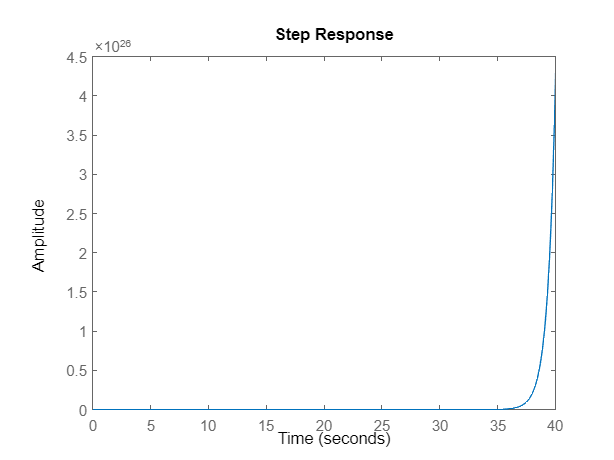

step(C_i*sys)


% sys = ss(1.5, 1, 1, 0);
% f = 10^5;
% [C_pid,info] = pidtune(sys,'PID', f);
% disp(info)
% C = feedback(C_pid*sys, 0.5)
% step(C)